parameter settings

clear all

nDelay = 300; %4 % # of delays
nDim = 3;

params.sigma = 10;
params.beta = 8/3;
params.rho = 28;
params.eta = sqrt(params.beta*(params.rho-1));

data generation

[t,x] = lorenzgen(params);

Visualize

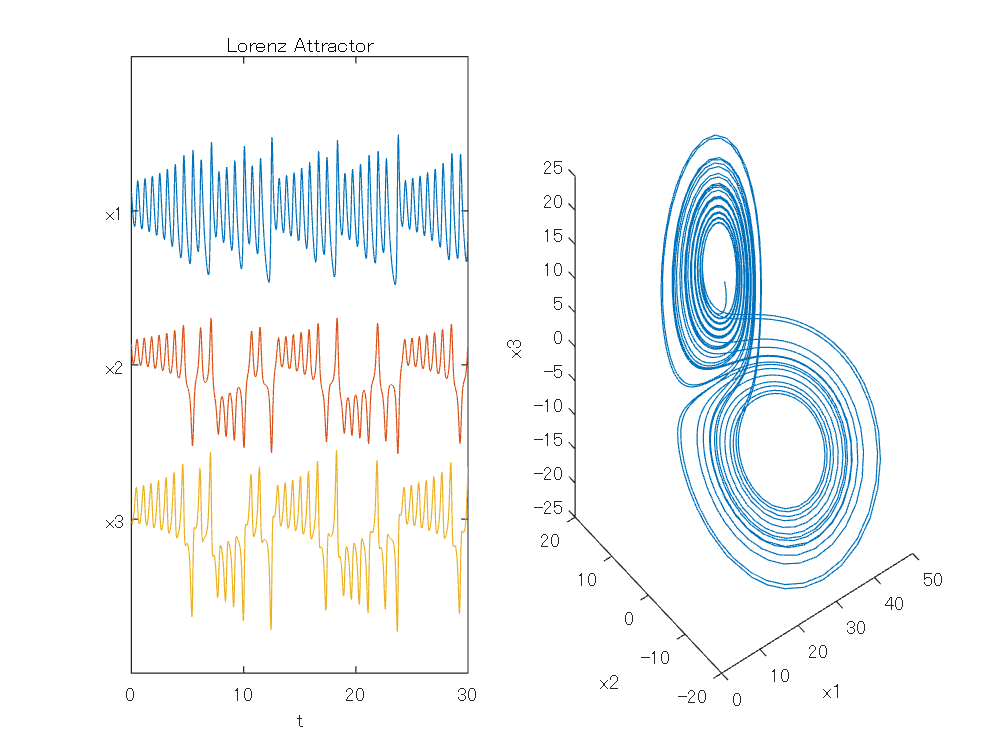

myplot(t,x);

Step 0 Preprocess w/ LSUN

Step 1 Delayed embedding and data matrix generation

ts = [];
H = [];
nRange = size(x,1)-1;
for k = 0:nRange-nDelay
    xkT = [];
    for iDelay = 0:nDelay
        xkT = cat(2,xkT,x(k+iDelay+1,:));
    end
    H = cat(2,H,xkT.');
end

H

H =    30.0000   29.6945   29.3613   29.0067   28.6359   27.7089   26.7620   25.8290   24.9334   23.9586   23.0771   22.3091   21.6779   21.2609   20.9852   20.8725   20.9471   21.2916   21.9493   22.9390   24.2483   25.6163   27.1179   28.6515   30.0961   31.3201   32.2138   32.7123   32.8015   32.4965   31.8533   30.9556   29.9082   28.9660   28.0021   27.0423   26.1055   25.0893   24.1341   23.2527   22.4572   21.6845   21.0556   20.5954   20.3352   20.3099   20.5633   21.1363   22.0585   23.1500
   10.4853    9.9720    9.4862    9.0287    8.6001    7.6915    6.9489    6.3676    5.9362    5.6025    5.4382    5.4299    5.5584    5.7682    6.0682    6.4540    6.9187    7.5354    8.2299    8.9765    9.7339   10.3639   10.9174   11.3471   11.6113   11.6777   11.5286   11.1686   10.6298    9.9197    9.1256    8.3112    7.5290    6.9201    6.3816    5.9237    5.5519    5.2357    5.0276    4.9237    4.9185    5.0221    5.2390    5.5669    6.0010    6.5363    7.1707    7.8933    8.6820    9

Step 2 SVD of H

[U,Sgm,V] = svd(H,'econ')

U =    -0.0575   -0.0046    0.0104   -0.0085    0.0008   -0.0431    0.0258   -0.0025    0.0063   -0.0199    0.0406   -0.0342    0.0267    0.0026   -0.0119   -0.0698    0.0140    0.0394   -0.0141    0.0089    0.0225    0.0061   -0.0447    0.0415   -0.0542    0.0308   -0.0791    0.0017   -0.0678    0.0607   -0.0250    0.0550   -0.0574    0.0627   -0.0183    0.0319    0.0137   -0.0770    0.0384   -0.0718   -0.0328    0.0693   -0.0824   -0.0746    0.0111    0.0233    0.0078   -0.1377    0.0500   -0.0178
   -0.0030    0.0187    0.0324   -0.0045   -0.0246   -0.0092    0.0012   -0.0403    0.0024   -0.0391   -0.0092    0.0166   -0.0097   -0.0320   -0.0079    0.0076    0.0052    0.0038   -0.0826    0.0122    0.0396    0.0413   -0.0117    0.0493   -0.0402   -0.0708    0.0265    0.0175    0.0646    0.0085    0.0720   -0.0243   -0.0464   -0.0152   -0.0263   -0.0150   -0.0346   -0.0249   -0.0652   -0.0011    0.0159    0.0679    0.0193    0.0343    0.0204    0.0156   -0.0392   -0.0011   -0.1080   -0

Sgm = 1.0e+04 *

    1.6102         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.2794         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

V =    -0.0280    0.0473    0.0123   -0.0011   -0.0163    0.0196    0.0149    0.0339    0.0027    0.0242   -0.0075    0.0333   -0.0239   -0.0039    0.0231    0.0155    0.0126   -0.0081    0.0195   -0.0042    0.0504    0.0083   -0.0244    0.0149    0.0057   -0.0366   -0.0493   -0.0074   -0.0013    0.0096    0.0004    0.0106   -0.0151    0.0139   -0.0231   -0.0093    0.0344   -0.0111    0.0023   -0.0119    0.0079    0.0310    0.0184    0.0310   -0.0094    0.0119    0.0235   -0.0256   -0.0226    0.0214
   -0.0280    0.0474    0.0130   -0.0017   -0.0167    0.0214    0.0132    0.0335    0.0057    0.0245   -0.0018    0.0334   -0.0235   -0.0055    0.0198    0.0203    0.0138   -0.0063    0.0232   -0.0147    0.0465    0.0067   -0.0225    0.0168    0.0067   -0.0379   -0.0430   -0.0137    0.0005    0.0096    0.0027    0.0109   -0.0130    0.0202   -0.0194   -0.0127    0.0323   -0.0135    0.0070   -0.0095    0.0024    0.0335    0.0176    0.0331   -0.0093    0.0164    0.0190   -0.0192   -0.0207    0

Step 3 PCT

iMode = 1

iMode = 1

ui = reshape(U(:,iMode),size(x,2),[]).'

ui =    -0.0575   -0.0030   -0.0029
   -0.0576   -0.0030   -0.0029
   -0.0576   -0.0030   -0.0029
   -0.0576   -0.0030   -0.0029
   -0.0576   -0.0030   -0.0030
   -0.0576   -0.0030   -0.0030
   -0.0576   -0.0030   -0.0030
   -0.0576   -0.0030   -0.0030
   -0.0576   -0.0030   -0.0030
   -0.0577   -0.0030   -0.0030


Visualize

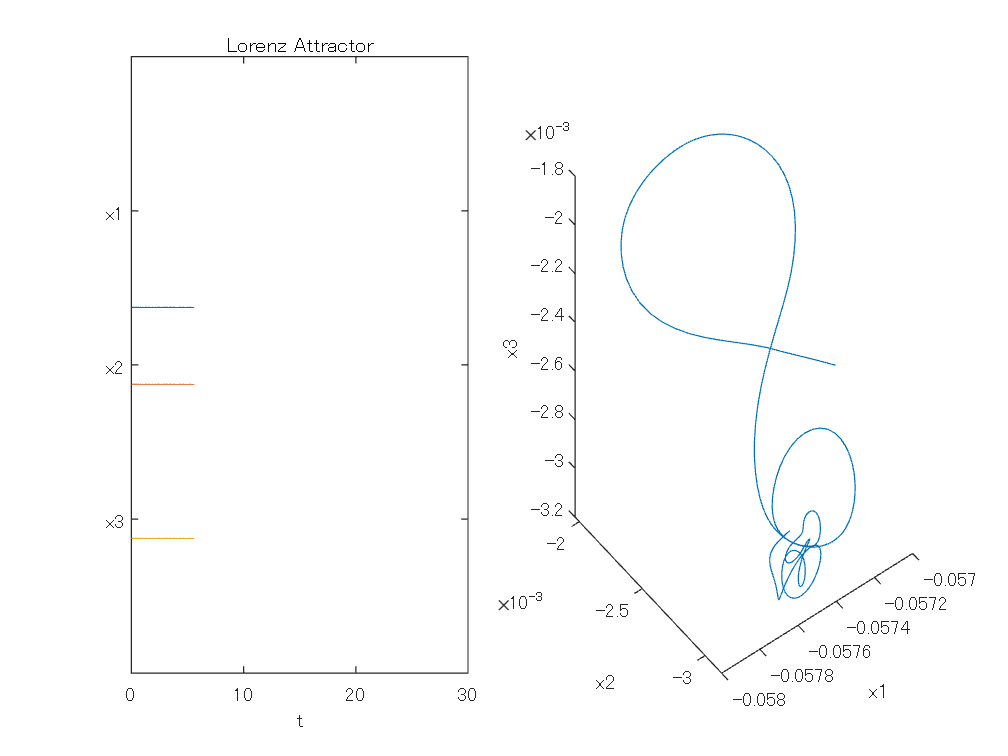

myplot(t(1:size(ui,1)),ui)

Step 3 Time step 

V0 = V(1:end-1,:);
V1 = V(2:end,:);
dtAplusI = (V1.')*pinv(V0.') 

dtAplusI =     1.0000    0.0001    0.0002   -0.0001   -0.0001   -0.0006   -0.0000   -0.0003    0.0001   -0.0001    0.0006   -0.0003    0.0001   -0.0001   -0.0001   -0.0008    0.0000    0.0004   -0.0004   -0.0002    0.0003    0.0002   -0.0001    0.0001   -0.0002    0.0002   -0.0001   -0.0001   -0.0002    0.0001    0.0002    0.0001   -0.0001    0.0003   -0.0001   -0.0000    0.0000   -0.0003    0.0002   -0.0002   -0.0002    0.0003    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0005   -0.0000    0.0001
    0.0003    0.9995   -0.0091    0.0006    0.0002    0.0020   -0.0001    0.0045    0.0004    0.0036    0.0018   -0.0005   -0.0004    0.0021    0.0004   -0.0013   -0.0005   -0.0003    0.0018   -0.0003   -0.0003   -0.0009   -0.0004   -0.0010    0.0001    0.0014   -0.0006   -0.0006   -0.0008   -0.0000   -0.0004    0.0004    0.0002    0.0006   -0.0000    0.0003    0.0004   -0.0001    0.0007   -0.0000   -0.0004   -0.0002   -0.0000   -0.0001   -0.0001   -0.0002    0.0003   -0.0004    0.00

Step 4 Discover forcinge signal

v0hat = V(1,:).';
vk = v0hat;
dtrk_ = 0;
dtr = [];
for k = 1:nRange-nDelay
    % True value
    vkp1 = V(k+1,:).';
    % Forcasted value
    vkp1hat = dtAplusI*vk;
    % Forcing signal
    dtrk_ = vkp1 - vkp1hat;
    % Update
    vk = vkp1;
    dtr = cat(2,dtr,dtrk_);
end


Learnable parameters

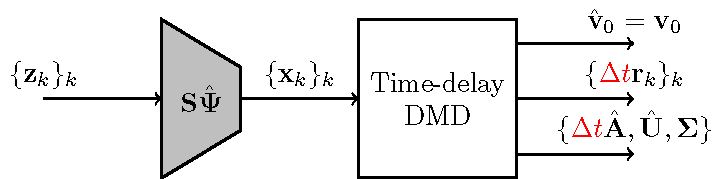

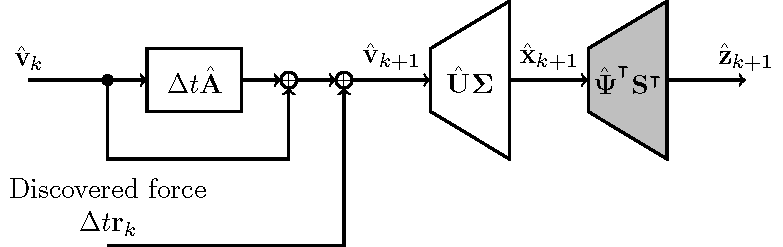

Parameters


$$\hat{\mathbf{v}}_0$$


v0hat

v0hat =    -0.0280
    0.0473
    0.0123
   -0.0011
   -0.0163
    0.0196
    0.0149
    0.0339
    0.0027
    0.0242



$$\{\Delta t \mathbf{r}_k\}$$


dtr

dtr =     0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000
    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   


$$\mathbf{I}+\Delta t \hat{\mathbf{A}}$$


dtAplusI

dtAplusI =     1.0000    0.0001    0.0002   -0.0001   -0.0001   -0.0006   -0.0000   -0.0003    0.0001   -0.0001    0.0006   -0.0003    0.0001   -0.0001   -0.0001   -0.0008    0.0000    0.0004   -0.0004   -0.0002    0.0003    0.0002   -0.0001    0.0001   -0.0002    0.0002   -0.0001   -0.0001   -0.0002    0.0001    0.0002    0.0001   -0.0001    0.0003   -0.0001   -0.0000    0.0000   -0.0003    0.0002   -0.0002   -0.0002    0.0003    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0005   -0.0000    0.0001
    0.0003    0.9995   -0.0091    0.0006    0.0002    0.0020   -0.0001    0.0045    0.0004    0.0036    0.0018   -0.0005   -0.0004    0.0021    0.0004   -0.0013   -0.0005   -0.0003    0.0018   -0.0003   -0.0003   -0.0009   -0.0004   -0.0010    0.0001    0.0014   -0.0006   -0.0006   -0.0008   -0.0000   -0.0004    0.0004    0.0002    0.0006   -0.0000    0.0003    0.0004   -0.0001    0.0007   -0.0000   -0.0004   -0.0002   -0.0000   -0.0001   -0.0001   -0.0002    0.0003   -0.0004    0.00


$$\hat{\mathbf{U}}$$


Uhat = U(1:nDim,:);
Uhat

Uhat =    -0.0575   -0.0046    0.0104   -0.0085    0.0008   -0.0431    0.0258   -0.0025    0.0063   -0.0199    0.0406   -0.0342    0.0267    0.0026   -0.0119   -0.0698    0.0140    0.0394   -0.0141    0.0089    0.0225    0.0061   -0.0447    0.0415   -0.0542    0.0308   -0.0791    0.0017   -0.0678    0.0607   -0.0250    0.0550   -0.0574    0.0627   -0.0183    0.0319    0.0137   -0.0770    0.0384   -0.0718   -0.0328    0.0693   -0.0824   -0.0746    0.0111    0.0233    0.0078   -0.1377    0.0500   -0.0178
   -0.0030    0.0187    0.0324   -0.0045   -0.0246   -0.0092    0.0012   -0.0403    0.0024   -0.0391   -0.0092    0.0166   -0.0097   -0.0320   -0.0079    0.0076    0.0052    0.0038   -0.0826    0.0122    0.0396    0.0413   -0.0117    0.0493   -0.0402   -0.0708    0.0265    0.0175    0.0646    0.0085    0.0720   -0.0243   -0.0464   -0.0152   -0.0263   -0.0150   -0.0346   -0.0249   -0.0652   -0.0011    0.0159    0.0679    0.0193    0.0343    0.0204    0.0156   -0.0392   -0.0011   -0.1080  


$$\mathbf{\Sigma}$$


Sgm

Sgm = 1.0e+04 *

    1.6102         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.2794         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

Step 5 w/ Discovered forcing signal

vkhat = v0hat;
dtrk = dtr(:,1);
Xhat = (Uhat*Sgm*vkhat).';
for k = 1:nRange-nDelay
    dtrk = dtr(:,k);
    vkp1hat = dtAplusI*vkhat + dtrk;
    Xhat = cat(1,Xhat,(Uhat*Sgm*vkp1hat).');
    % Update
    vkhat = vkp1hat;
end

Visualize

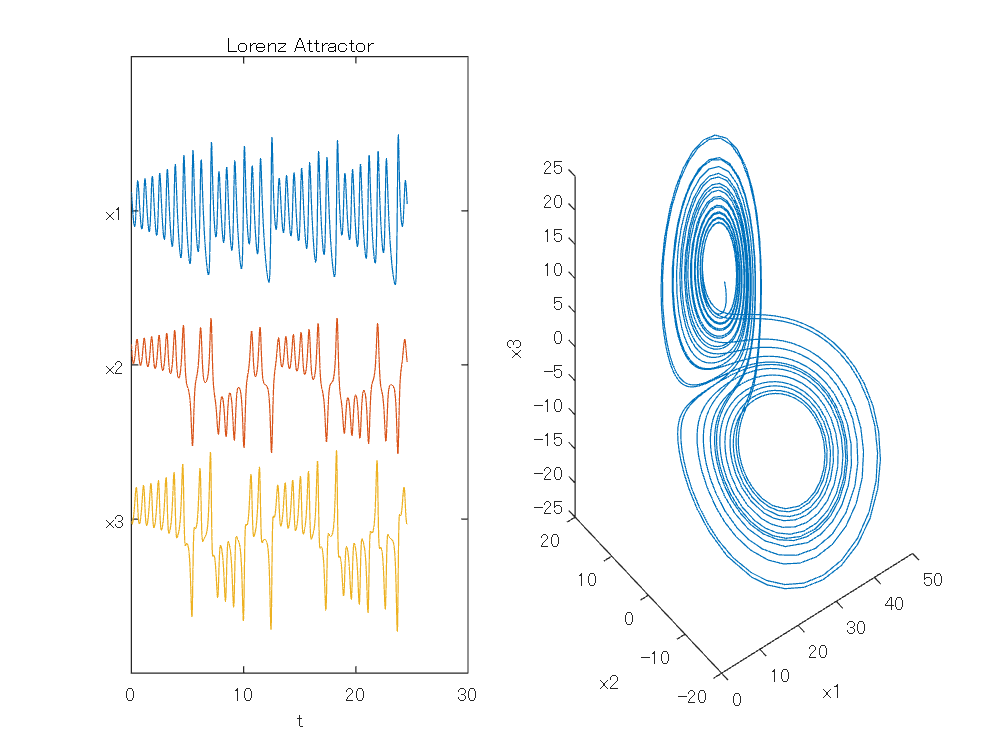

myplot(t(1:size(Xhat,1)),Xhat);

Step 6 w/o Discorverd forcing signal


vkhat = v0hat;
dtrk = dtr(:,1);
Xhat = (Uhat*Sgm*vkhat).';
for k = 1:nRange-nDelay
    dtrk = dtr(:,k);
    vkp1hat = dtAplusI*vkhat; % + dtrk;
    Xhat = cat(1,Xhat,(Uhat*Sgm*vkp1hat).');
    % Update
    vkhat = vkp1hat;
end

Visualize

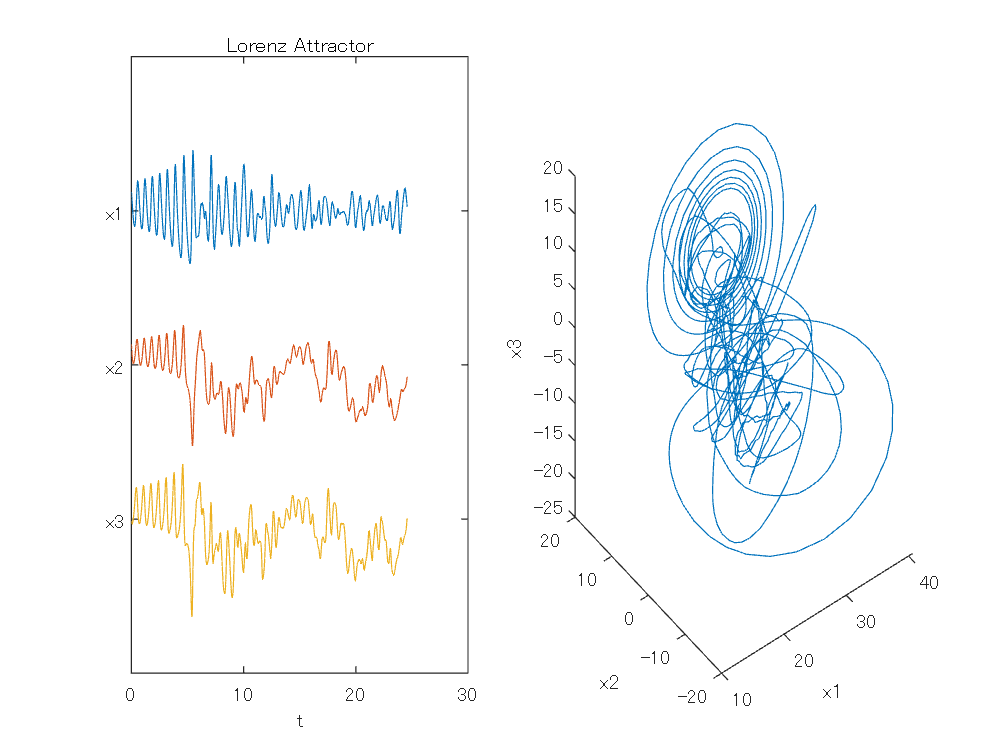

myplot(t(1:size(Xhat,1)),Xhat);

Post-processing w/ LSUN

function [t,y] = lorenzgen(params)

sigma = params.sigma;
beta = params.beta;
rho = params.rho;
eta = params.eta;

A = [ -beta 0 eta;
    0 -sigma sigma;
    -eta rho -1 ];
v0 = [rho-1 eta eta]';
y0 = v0 + [3 2 -4]';
tspan = [0 30];

[t,y] = ode45(@(t,y) lorenzeqn(t,y,A), tspan, y0);
end

function ydot = lorenzeqn(t,y,A)

A(1,3) = y(2);
A(3,1) = -y(2);
ydot = A*y;

end

function myplot(t,x)

subplot(1,2,1)
plot(t,[x(:,1)+15 x(:,2)-5 x(:,3)-45]);
axis([0 30 -80 80])
set(gca,'ytick',[-40 0 40],'yticklabel',{'x3','x2','x1'})
xlabel('t')
title('Lorenz Attractor')

subplot(1,2,2)
plot3(x(:,1),x(:,2),x(:,3));
xlabel('x1')
ylabel('x2')
zlabel('x3')

end